n = 20; k = 100;
pol = getpol1(n)

$$pol = \left(\begin{array}{ccccccccccccccccccccc} 1 & -210 & 20615 & -1256850 & 53327946 & -1672280820 & 40171771630 & -756111184500 & 11310276995381 & -135585182899530 & 1307535010540395 & -10142299865511450 & 63030812099294896 & -311333643161390640 & 1206647803780373360 & -3599979517947607200 & 8037811822645051776 & -12870931245150988800 & 13803759753640704000 & -8752948036761600000 & 2432902008176640000 \end{array}\right)$$

cond_pol = condpol(pol)

cond_pol = 	1.0e+14 *

    5.7926    0.0062    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


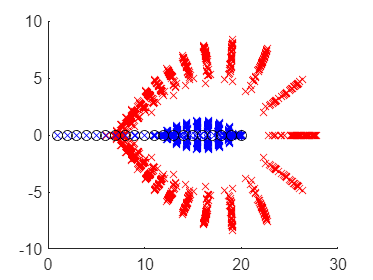

clf; figure(1); hold on;
for i=1:k
    vect = normrnd(0, 1e-5, 1, n+1); % VA normala: 10^-5 pt ca al doilea param e sqrt(dispersie) = deviatia standard
    pol_pert = pol+vect;
    plot_pol_roots(pol_pert, 'red', 'marker');

    % trebuie centrat in 0, media e 1/2*(a+b), dispersia e 1/12*(b-a)
    b = sqrt(3) * 1e-10;
    vect = unifrnd(-b, b, 1, n+1); % VA uniforma
    pol_pert = pol+vect;
    plot_pol_roots(pol_pert, 'blue', 'marker');
end
plot_pol_roots(pol, 'black', 'circle');
hold off;

clear;
n = 20; k = 20;
pol = getpol2(n)

$$pol = \left(\begin{array}{ccccccccccccccccccccc} 1 & \frac{1}{2} & \frac{1}{4} & \frac{1}{8} & \frac{1}{16} & \frac{1}{32} & \frac{1}{64} & \frac{1}{128} & \frac{1}{256} & \frac{1}{512} & \frac{1}{1024} & \frac{1}{2048} & \frac{1}{4096} & \frac{1}{8192} & \frac{1}{16384} & \frac{1}{32768} & \frac{1}{65536} & \frac{1}{131072} & \frac{1}{262144} & \frac{1}{524288} & \frac{1}{1048576} \end{array}\right)$$

cond_pol = condpol(pol)

cond_pol =     0.0000    0.0000    0.0001    0.0002    0.0005    0.0011    0.0043    0.0172    0.0344    0.0348    0.0364    0.0603    0.0881    0.1645    0.3366    0.8394    3.0250    6.0500    6.7150   10.7700


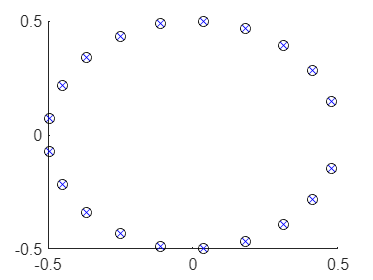

clf; figure(2); hold on;
for i = 1:k
    vect1 = normrnd(0, 1e-5, 1, n+1); 
    roots_perturbed1 = (roots(pol) + vect1)'; % Add perturbation to roots
    plot(roots_perturbed1, 'rx')

    vect2 = unifrnd(0, 1e-10, 1, n+1); 
    roots_perturbed2 = (roots(pol) + vect2)'; % Add perturbation to roots
    plot(roots_perturbed2, 'bx')
end
plot_pol_roots(pol, 'black', 'circle');
hold off;

function nc = condpol(p, r)
    % If roots are not provided, compute them
    if nargin < 2
        r = roots(p)';
    end
    
    % Compute the derivative p'(x) (polyder does not work for some reason)
    dp = [length(p)-1:-1:1] .* p(1:end-1); %derivata;
    
    % convert to double
    dp = double(dp);
    r = double(r);
    
    % Calculate the value of the derivative at each root
    val_df = polyval(dp, r);
    
    % Calculate the absolute values of the polynomial coefficients
    abs_p = abs(p);
    
    % Calculate the condition number
    nc = double(abs(val_df .* r) ./ abs_p(2:end));
end

function plot_pol_roots(pol, color, type)
    % Find the roots of the polynomial
    roots_pol = roots(pol);
    
    % Extract real and imaginary parts of roots
    real_part = real(roots_pol);
    imag_part = imag(roots_pol);
    
    % Plot roots based on the type specified
    if strcmpi(type, 'point')
        plot(real_part, imag_part, [color, 'o'], 'MarkerFaceColor', color);
    elseif strcmpi(type, 'circle')
        plot(real_part, imag_part, ['o', color]);
    elseif strcmpi(type, 'marker')
        plot(real_part, imag_part, [color, 'x']);
    else
        error('Invalid type. Specify ''point'', ''circle'', or ''marker''.');
    end
end

function rez = getpol1(n)
    syms x
    rez = 1;
    for i=1:n
        rez = rez * (x-i);
    end
    pol=expand(rez);
    rez=fliplr(coeffs(pol, x));
end

function rez = getpol2(n)
    syms x
    rez = x^n;
    for i=1:n
        coef = 2^(-i);
        rez = rez + coef * x^(n-i);
    end
    pol=rez;
    rez=fliplr(coeffs(pol, x));
end